[y_noise, Fs_noise] = audioread("sound_sample\noise.wav");
[y_music, Fs_music] = audioread("sound_sample\music_sample.wav");

%refine data
y_remusic = y_music(1:length(y_music)/3,1)*0.4;
y_renoise = y_noise(1:length(y_music)/3,1);

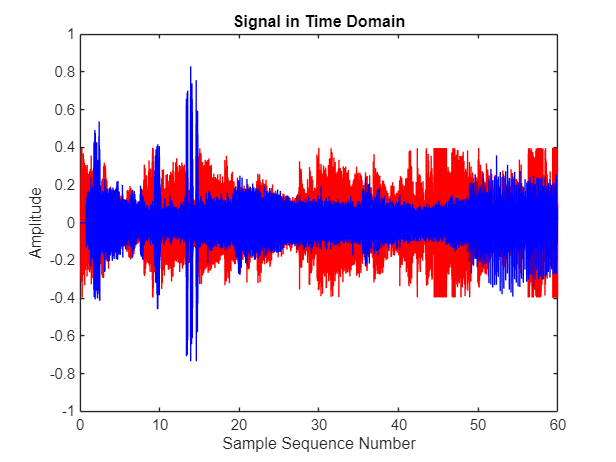

% Plot informations

% Mix tape
y_mixture = y_remusic + y_renoise;

plot_numberOfSampler = linspace(0,length(y_music)/Fs_music, length(y_remusic));
figure;
plot(plot_numberOfSampler, y_remusic,Color="r");
hold on;
plot(plot_numberOfSampler, y_renoise, Color="b");
title('Signal in Time Domain')
xlabel('Sample Sequence Number')
ylabel('Amplitude')
ylim([-1,1])
hold off;

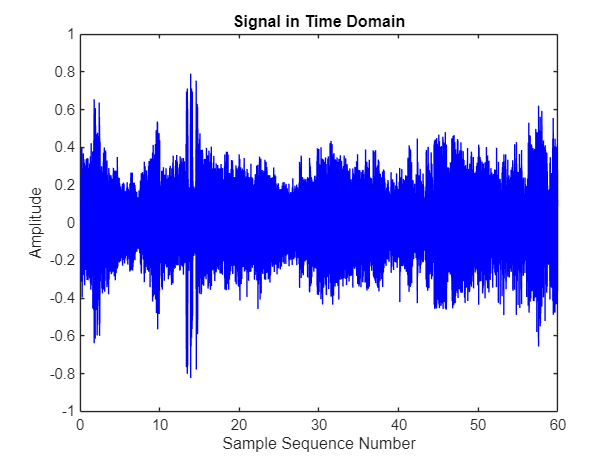

figure;
plot(plot_numberOfSampler, y_mixture, color="b");
title('Signal in Time Domain')
xlabel('Sample Sequence Number')
ylabel('Amplitude')
ylim([-1,1])
hold off;

% Audio player
%the_audioPlayer = audioplayer(y_mixture, Fs_music)
sound(y_mixture, Fs_music)
%play(the_audioPlayer)

% Define Weight of noise reference received by mic
Wn = [0 0 0 0 0 0 0 0]'

Wn =      0
     0
     0
     0
     0
     0
     0
     0


output_signal = EstimateCancelingSignal(y_renoise, 128)

num_sample = 881872

cancellingSignal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0

learning_rate = 0.5000

Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in EstimateCancelingSignal (line 24)
    cancellingSignal(n)= Filter_weight * x_n'

Related documentation

plot(linspace(0,length(y_music)/Fs_music, length(output_signal)), output_signal)

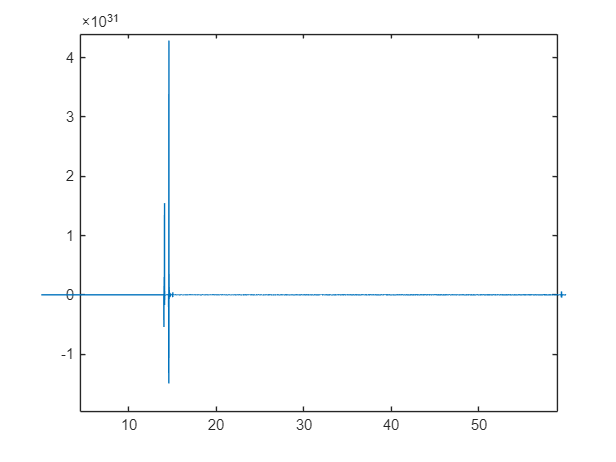

plot(linspace(0,length(y_music)/Fs_music, length(err)), err)